This script is for simulation of FLP to decide the minimum photon count per second for a robust and reliable fluorescence lifetime photometry signal, based on the autofluorescence levels.

This is the 4th time running this simulation. 

On top of the 3rd time running, some issues are summarized in the powerpoint in iCloud/ChenLab_Data/simulation_FLP_20220209/simulation_summary_for_threshold.pptx.

Basically this time I'm trying to

- Check the autofluorescence under that laser power.

- Add more background in autofluorescence for background correction purpose.

- Add more samples in the higher photon range

The properties of autofluorescence is characterized in the file 'Volumes/yaochen/Active/Pingchuan/2022SPR/20220208_PM13_autofluo_001'.

The analysis of autofluorescence is specified in live script '/Users/pingchuanma/Desktop/ChenLab_Data/MATLAB analysis/FLP_simulation_20220209.mlx'

Then I need some information of the properties of ACh 3.0 in FLP set-up.

I turned to a newly collected dataset: '/Volumes/yaochen/Active/Pingchuan/2021Fall/FLP/122121_all_max_LaserPower_001/122121_all_max_LaserPower_001', continuous aquistion data_43 is a 120-second recording of this mouse #1263 that has relatively high expression of ACh 3.0, which gives a photon count of around 1042135 per second.

SimulationName='simulation_FLP_02102022';
mkdir(SimulationName); % make directory that contains all the simulated data


% tau1=2.706;
% p1=0.8;
% tau2=0.2613;
% p2=0.2; % copied from /Users/pingchuanma/Library/CloudStorage/Box-Box/ChenLab/Pingchuan/Ach FLIM Manuscript Preparation/Figure 2-Simulation/Simulation_instructions'
% PopulationName='Simulation_02092022_FLP_population';
% 
% cd(SimulationName);
% GenPop256_FLP(100000, p1, p2, tau1, tau2, PopulationName);
% 
% % autofluorescence
% 
tau1=2.4922;
p1=0.2700;
tau2=0.4069;
p2=0.7300;
PopulationName='Simulation_02102022_autofluo_population';

GenPop256_FLP(100000, p1, p2, tau1, tau2, PopulationName);

To simulate, one missing parameter is the gaussian width from fitting, which needs to be re-collected.

It turns out that the gaussian width from autofluorescence fitting and ACh 3.0 fluorescence fitting is different.

Another question is there are two ways of adding autofluorescence: 1) from fitting and simulation; 2) from empirical shape of the autofluorescence. For the 1st one, I've collected the tau1, tau2, p1, p2 and the corresponding width from gaussian fitting. For the 2nd one, I need to recollect the empirical shape of the histograms.

% PM13_lifetime_histograms_normolized=[];
% 
% for i=1:size(PM13_time,1)
%     PM13_lifetime_histograms_normolized(:,i)=PM13_lifetime_histograms(:,i)/max(PM13_lifetime_histograms(:,i));
% end
% 
% PM13_lifetimes=zeros(256,1);
% 
% for i=1:256
%     PM13_lifetimes(i)=mean(PM13_lifetime_histograms_normolized(i,:));
% end

% KQ17_lifetime_histograms_normolized=[];
% 
% for i=1:size(KQ17_time,1)
%     KQ17_lifetime_histograms_normolized(:,i)=KQ17_lifetime_histograms(:,i)/max(KQ17_lifetime_histograms(:,i));
% end
% 
% KQ17_lifetimes=zeros(256,1);
% 
% for i=1:256
%     KQ17_lifetimes(i)=mean(KQ17_lifetime_histograms_normolized(i,:));
% end


% ACh1263_lifetime_histograms_normolized=[];
% 
% for i=1:size(ACh1263_time,1)
%     ACh1263_lifetime_histograms_normolized(:,i)=ACh1263_lifetime_histograms(:,i)/max(ACh1263_lifetime_histograms(:,i));
% end
% 
% ACh1263_lifetimes=zeros(256,1);
% 
% for i=1:256
%     ACh1263_lifetimes(i)=mean(ACh1263_lifetime_histograms_normolized(i,:));
% end

The next issue is to decide 'prf', which here is the gaussian distribution function to convolute the signal. The parameters needed is the mean and the sigma. I decide the mean based on one prf file I collected before. The mean corresponds to the peak channel of the prf (which is 37, 37*(25/256)=3.6133 ns). Then the question is what's the relationship between the sigma and beta6, which is called the Gaussian width.

width=0.1554;
miu=3.6133;
x=1:1:256;
x=x*(25/256);
Gaussian_y=1/(width*sqrt(2*pi))*exp(-(x-miu).^2/(2*width^2));
figure
plot(x,Gaussian_y)

Gaussian_y=Gaussian_y/sum(Gaussian_y);
figure
plot(x,Gaussian_y)
hold on
plot(x,prf)
legend('Gaussian','prf')

Gaussian_y=Gaussian_y';

Relationship between p1 and average tau:

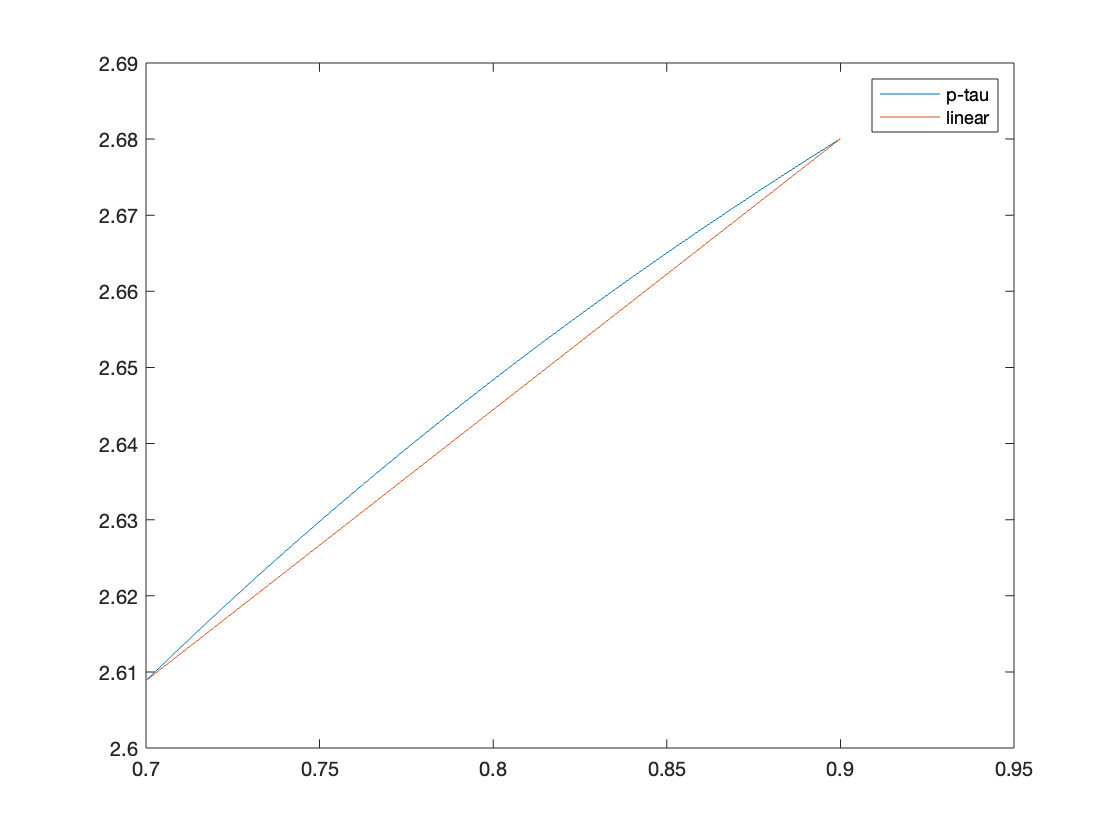

tau1=2.706;
tau2=0.2613;
tau3=2.4922;
p_auto=0.2700;
tau4=0.4069;

p=0.7:0.0002:0.9;
mean_tau=zeros(1,1001);
mean_auto=(tau3*tau3*p_auto+tau4*tau4*(1-p_auto))/(tau3*p_auto+tau4*1-p_auto);

for i=1:1001
    mean_tau(i)=(tau1*tau1*p(i)+tau2*tau2*(1-p(i)))/(tau1*p(i)+tau2*(1-p(i)));
end

line_x=[0.7 0.9];
line_y=[mean_tau(1) mean_tau(1001)];

figure
plot(p,mean_tau)
hold on
plot(line_x,line_y)
legend('p-tau','linear')

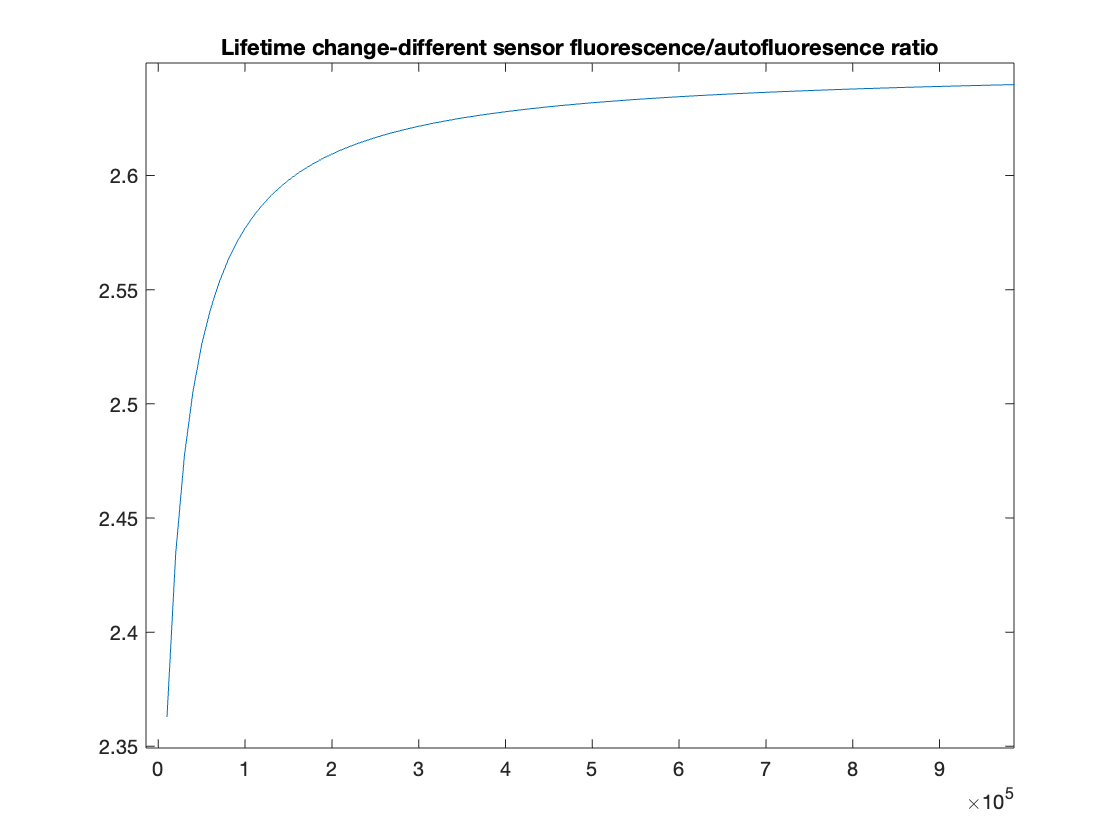


photonsize=10000:10000:1000000;
mean_auto_ACh=zeros(1,size(photonsize,2));

for i=1:100
    mean_auto_ACh(i)=(photonsize(i)*mean_tau(500)+20000*mean_auto)/(photonsize(i)+20000);
end

figure
plot(photonsize,mean_auto_ACh)
title('Lifetime change-different sensor fluorescence/autofluoresence ratio')

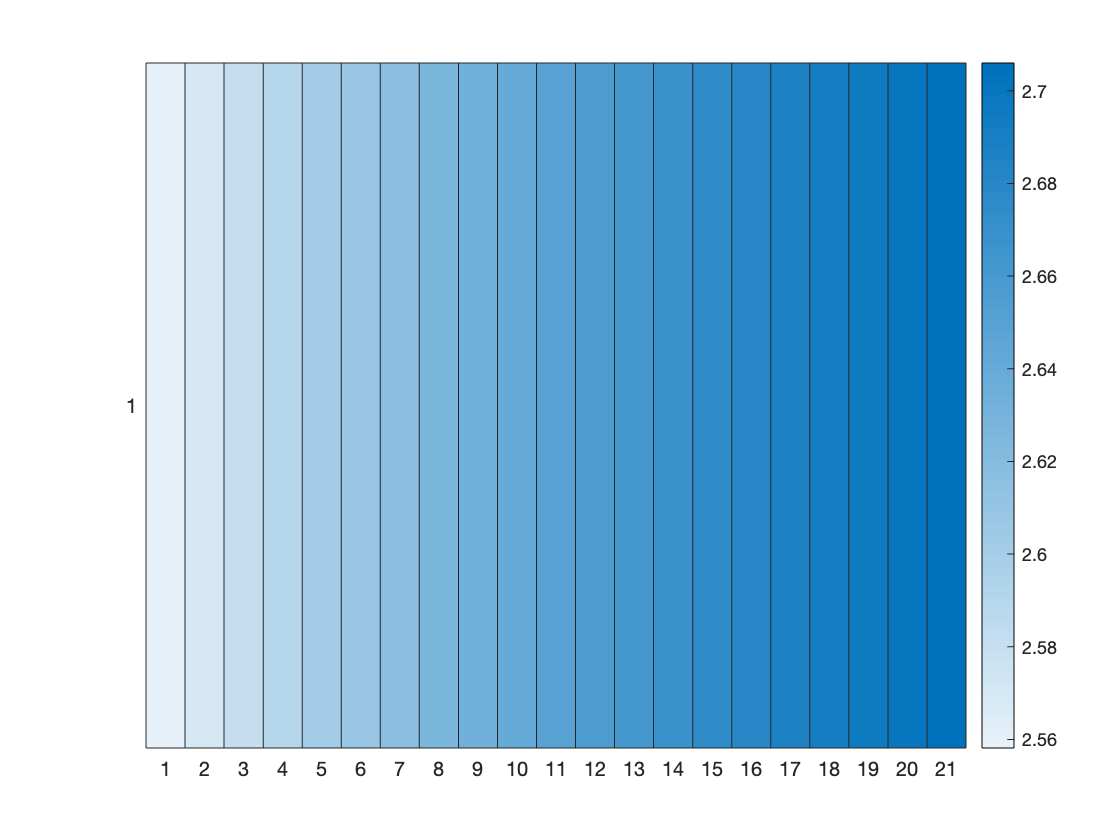

ans =   HeatmapChart with properties:

        XData: {21×1 cell}
        YData: {'1'}
    ColorData: [2.5581 2.5694 2.5801 2.5902 2.5997 2.6088 2.6175 2.6258 2.6337 2.6412 2.6484 2.6553 2.6618 2.6682 2.6742 2.6800 2.6856 2.6910 2.6962 2.7012 2.7060]

  Show all properties


p_2=0.6:0.02:1.0;
mean_tau_2=zeros(1,21);
tau1=2.706;
tau2=0.2613;

for i=1:21
    mean_tau_2(i)=(tau1*tau1*p_2(i)+tau2*tau2*(1-p_2(i)))/(tau1*p_2(i)+tau2*(1-p_2(i)));
end

figure 
heatmap(mean_tau_2)

% SS=200000;
% AF=200000;
% PopulationName='Simulation_122221_FLP_population.mat';
% autofluo=KQ17_lifetimes/sum(KQ17_lifetimes);
% global Gaussian_y autofluo prf
% 
% mkdir(num2str(SS))
% for i=1:50
%     samplename=[num2str(SS),'/',num2str(i),'_noauto.mat'];
%     FLIMsim256_FLP(SS,AF,PopulationName,samplename)
% end



cd(SimulationName)
AF=20000;
PopulationName='Simulation_02092022_autofluo_population';
% autofluo=KQ17_lifetimes/sum(KQ17_lifetimes);
global Gaussian_y prf
SS_all=zeros(1,50);

mkdir([num2str(AF),'_AF'])
for i=1:50
    SS=randi(2000)+19000; % 10% of fluctuation
    SS_all(i)=SS;
    samplename=[num2str(AF),'_AF/',num2str(i),'_auto.mat'];
    FLIMsim256_FLP(SS,AF,PopulationName,samplename)
end

figure
plot(SS_all)




p1_samples=0.6:0.02:1.0;
AF=20000;
tau1=2.706;
tau2=0.2613;
% SS_samples=[20000 40000 60000 80000 100000 120000 140000 160000 180000 200000 ...
%     220000 240000 260000 280000 300000 320000 340000 360000 380000 400000 ...
%     420000 440000 460000 480000 500000];
SS_samples=20000:20000:500000;
% autofluo=KQ17_lifetimes/sum(KQ17_lifetimes);
global Gaussian_y prf

for i=1:21
    p1=p1_samples(i);
    p2=1-p1;
    PopulationName=['Simulation_02102022_FLP_population_',num2str(p1),'.mat'];
    GenPop256_FLP(100000, p1, p2, tau1, tau2, PopulationName);
    for j=1:25
        SS=SS_samples(j);
        mkdir([num2str(SS),'_',num2str(p1)])
        for k=1:50
            samplename=[num2str(SS),'_',num2str(p1),'/',num2str(k),'_noauto.mat'];
            FLIMsim256_FLP(SS,AF,PopulationName,samplename)
        end
    end
end



% plot the simulated data and data from real experimental collection to
% compare
load('20000_AF/1_auto.mat')
n_auto=n';
n_auto_b=n_auto+6; % add 6 as background
load('280000_0.7/1_noauto.mat')
n_ACh=n';

n_sim=n_auto_b+n_ACh+6;

n_real=spc.lifetimes{1}; % have to load a FLP data from real experiment first

n_sim_norm=n_sim/max(n_sim);
n_real_norm=n_real/max(n_real);



figure
semilogy(n_sim_norm,'LineWidth',3)
hold on
semilogy(n_real_norm,'LineWidth',3)
legend('simulation','experiment')
title('AutoFluo+AChFluo')

n_auto_norm=n_auto/max(n_auto);
n_auto_b_norm=n_auto_b/max(n_auto_b);

n_auto_real=spc.lifetimes{1}; % have to load a FLP data first

n_auto_real_norm=n_auto_real/max(n_auto_real);

figure
semilogy(n_auto_norm, 'LineWidth',3)
hold on
semilogy(n_auto_real_norm, 'LineWidth',3)
legend('simulation','experiment')
title('Autofluo_no_backcorr')

figure
semilogy(n_auto_b_norm, 'LineWidth',3)
hold on
semilogy(n_auto_real_norm, 'LineWidth',3)
legend('simulation','experiment')
title('Autofluo+backcorr')


p1_samples=0.6:0.02:1.0;
AF=20000;
tau1=2.706;
tau2=0.2613;
ch=1;

SS_samples=20000:20000:500000;

for i=1:21
    p1=p1_samples(i);
 

    for j=1:25
        SS=SS_samples(j);
%         mkdir([num2str(SS),'_',num2str(p1),'_auto'])
        
        tau_avg=[];
        tau_avgTrunc=[];
        tau_empTrunc=[];
        photoncount=[];
        p1_sim=[];
        chi2=[];
        beta2=[];
        beta4=[];
        beta5=[];
        beta6=[];
        lifetime_histograms=[];
        
        for k=1:50
            samplename=[num2str(SS),'_',num2str(p1),'/',num2str(k),'_noauto.mat'];
            load(samplename)
            n_ACh=n';
            AFname=['20000_AF/',num2str(k),'_auto.mat'];
            load(AFname);
            n_auto=n';
            spc.lifetimes{1}=n_ACh+n_auto+6;
            
            spc_fitexp2gaussGY(ch);
%             spc_adjustTauOffset(1);
            
            
            photoncount(k)=sum(spc.lifetimes{1});
            p1_sim(k)=spc.fits{ch}.beta1/(spc.fits{ch}.beta1+spc.fits{ch}.beta3);
            tau_avg(k)=spc.fits{ch}.avgTau; % mean Tau calculated from fit
            tau_avgTrunc(k)=spc.fits{ch}.avgTauTrunc;
            tau_empTrunc(k)=spc.fits{ch}.EmpTauTrunc;
            chi2(k)=spc.fits{ch}.redchisq;
            beta2(k)=spc.fits{ch}.beta2;
            beta4(k)=spc.fits{ch}.beta4;
            beta5(k)=spc.fits{ch}.beta5;
            beta6(k)=spc.fits{ch}.beta6;
            lifetime_histograms=[lifetime_histograms spc.lifetimes{1}];
            
        end
        
        photoncount=transpose(photoncount);
        tau_avg=transpose(tau_avg);
        tau_avgTrunc=transpose(tau_avgTrunc);
        tau_empTrunc=transpose(tau_empTrunc);
        p1_sim=transpose(p1_sim);
        chi2=transpose(chi2);
        beta2=transpose(beta2);
        beta4=transpose(beta4);
        beta5=transpose(beta5);
        beta6=transpose(beta6);
        
        result_name=[num2str(SS),'_',num2str(p1),'_result.mat'];
        save(result_name,'photoncount', 'tau_avg','tau_avgTrunc','tau_empTrunc', 'p1_sim','chi2','beta2','beta4','beta5','beta6','lifetime_histograms')
    end
end


p1_samples=0.6:0.02:1.0;
AF=20000;
tau1=2.706;
tau2=0.2613;
ch=1;

SS_samples=20000:20000:500000;

for i=1:21
    p1=p1_samples(i);
    eval(['tau_empTrunc_',num2str(i),'=[];'])
    for j=1:25
        SS=SS_samples(j);
        result_name=[num2str(SS),'_',num2str(p1),'_result.mat'];
        load(result_name);
        eval(['tau_empTrunc_',num2str(i),'=[tau_empTrunc_',num2str(i),' tau_empTrunc];'])
    end
end

for j=1:25
    SS=SS_samples(j);
    eval(['tau_empTrunc_',num2str(SS),'=[];'])
    
    for i=1:21
        p1=p1_samples(i);
        result_name=[num2str(SS),'_',num2str(p1),'_result.mat'];
        load(result_name);
        eval(['tau_empTrunc_',num2str(SS),'=[tau_empTrunc_',num2str(SS),' tau_empTrunc];'])
    end
end



calculation of the mean and std of each condition of simulation

std_all=[];
mean_all=[];

for i=1:25
    SS=SS_samples(i);
    eval(['this_samplesize=tau_empTrunc_',num2str(SS),';'])
    std_all=[std_all;std(this_samplesize)];
    mean_all=[mean_all;mean(this_samplesize)];
end



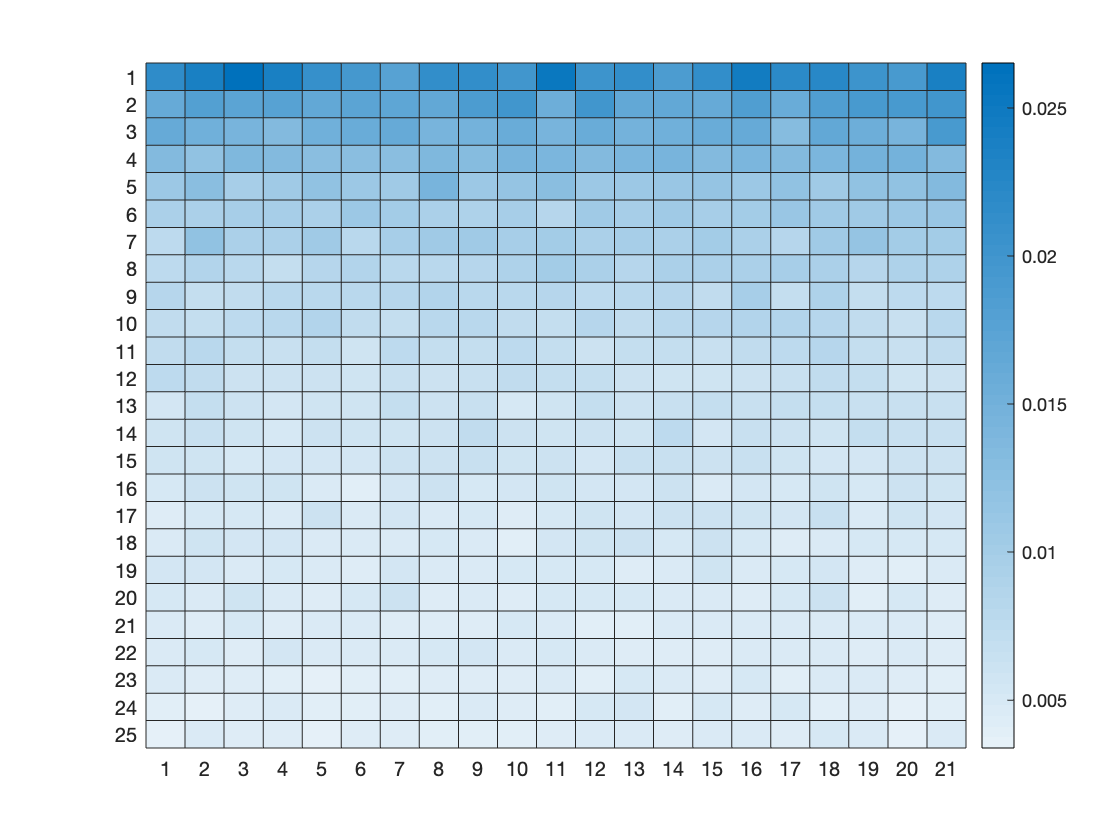

ans =   HeatmapChart with properties:

        XData: {21×1 cell}
        YData: {25×1 cell}
    ColorData: [25×21 double]

  Show all properties


figure
heatmap(std_all)

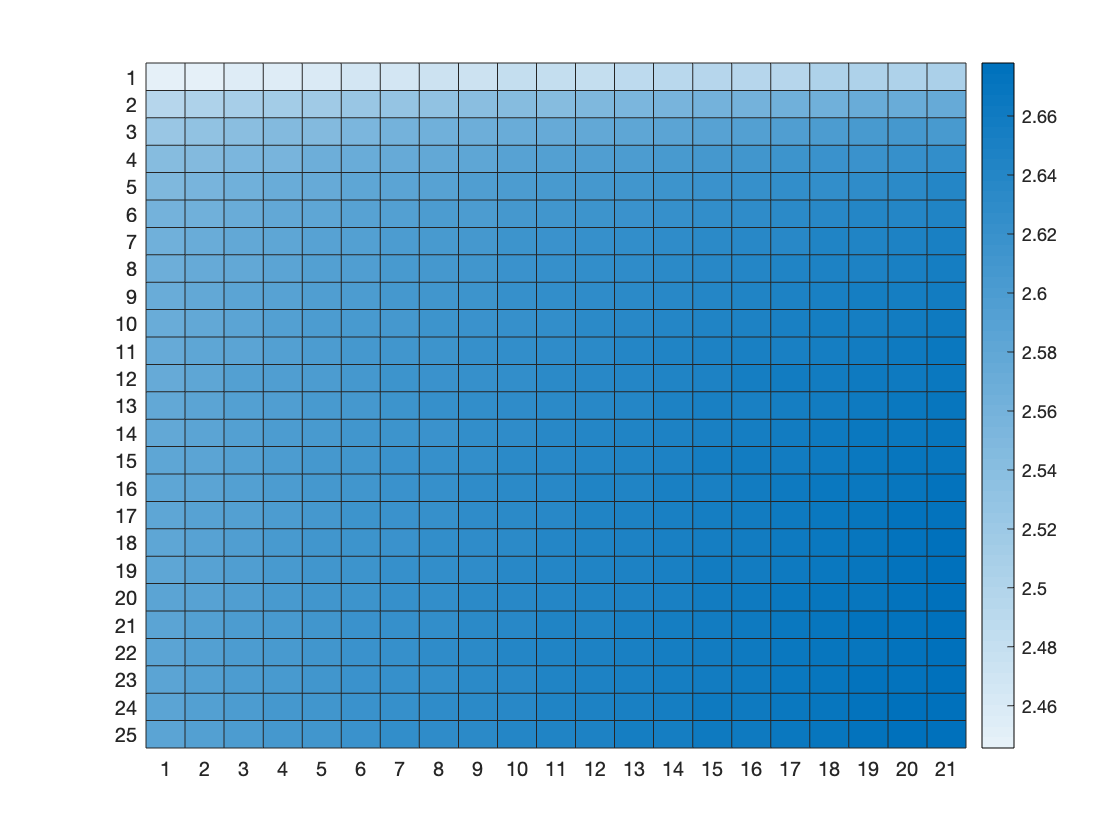

ans =   HeatmapChart with properties:

        XData: {21×1 cell}
        YData: {25×1 cell}
    ColorData: [25×21 double]

  Show all properties



figure
heatmap(mean_all)

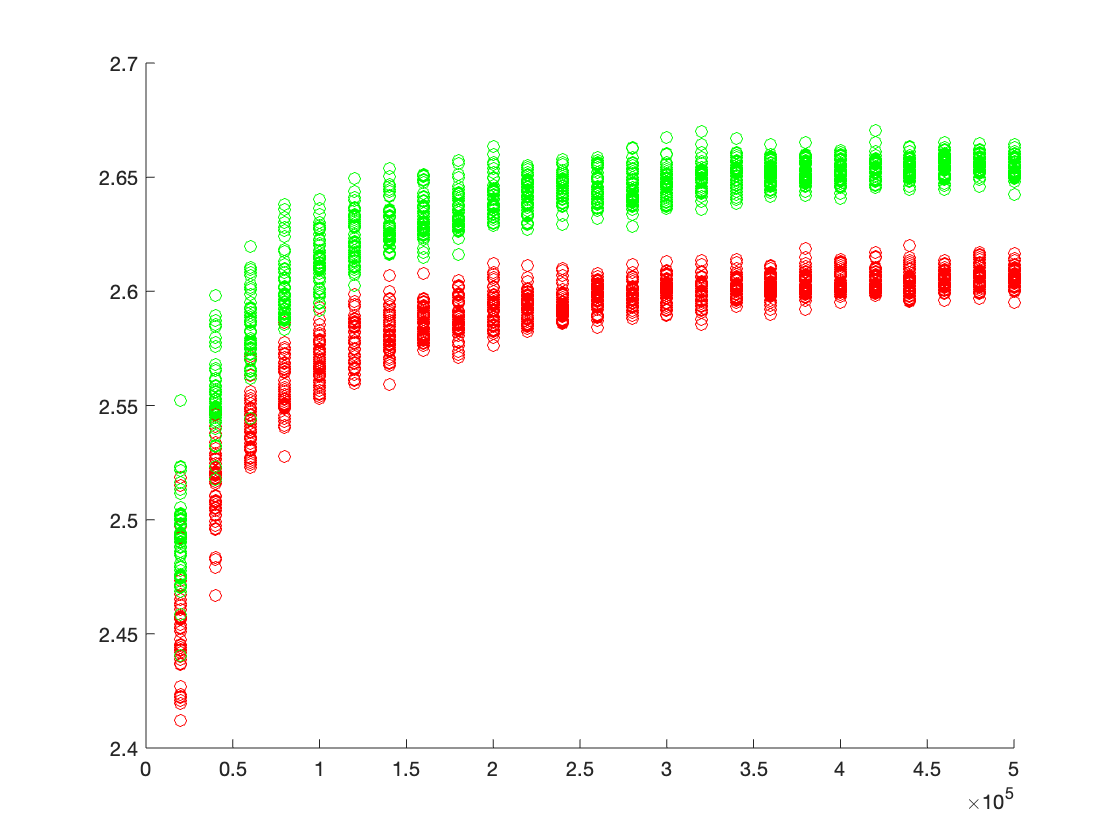



figure
for i=1:25
    scatter_plot_x=zeros(50,1);
    scatter_plot_x=scatter_plot_x+SS_samples(i);
    scatter(scatter_plot_x,tau_empTrunc_4(:,i),'red');
    hold on
end


for i=1:25
    scatter_plot_x=zeros(50,1);
    scatter_plot_x=scatter_plot_x+SS_samples(i);
    scatter(scatter_plot_x,tau_empTrunc_14(:,i),'green');
    hold on
end


hold off

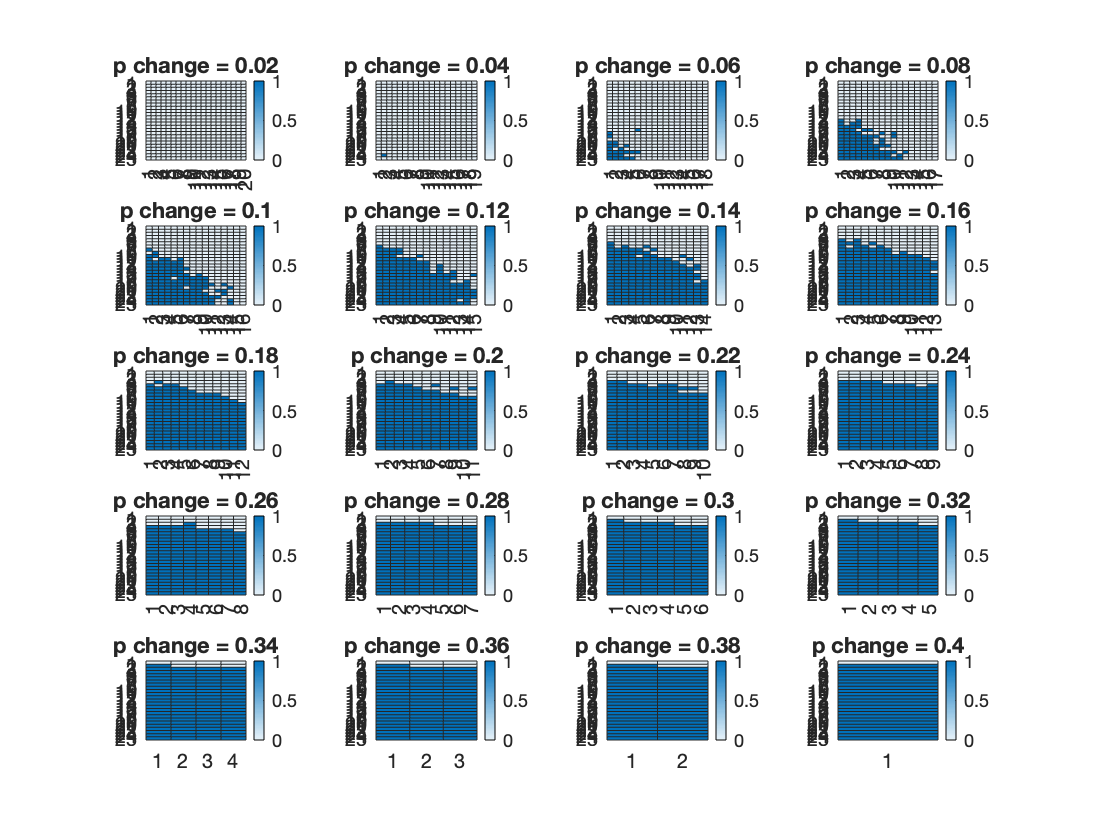

for j=1:20
    mean_all_diff=zeros(25,21-j);
    for i=1:21-j
        mean_all_diff(:,i)=mean_all(:,i+j)-mean_all(:,i);
    end
    
    diff=mean_all_diff/3.96-std_all(:,1:(21-j));
    diff_plot=diff;
    diff_plot(find(diff>=0))=1;
    diff_plot(find(diff<0))=0;
    subplot(5,4,j)
    h=heatmap(diff_plot);
    h.Title=['p change = ',num2str(0.02*j)];
    h.ColorLimits=[0 1];
end


% mean_change=zeros(1,20);
% 
% for i=1:20
%     mean_change(i)=mean_tau_2(i+1)-mean_tau_2(i);
% end
% 
% figure
% heatmap(mean_change)


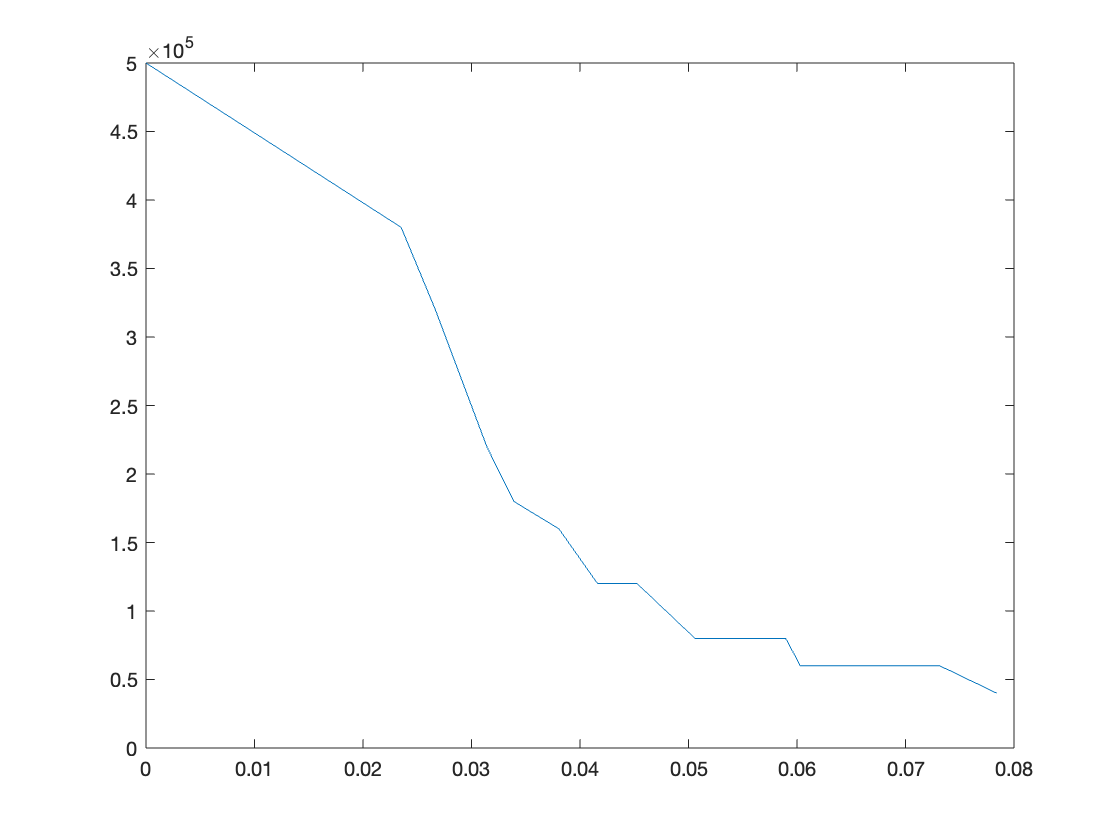

detectable_line=[25 25 25 25 25 25 19 16 11 9 8 6 6 4 4 4 3 3 3 2];
detectable_lft=zeros(1,20);

for j=1:20
    mean_all_diff=zeros(25,21-j);
    for i=1:21-j
        mean_all_diff(:,i)=mean_all(:,i+j)-mean_all(:,i);
    end
    
    if detectable_line(j)==25
        detectable_lft(j)=0;
    else
        detectable_lft(j)=min(mean_all_diff(detectable_line(j),:));
    end
    
%     subplot(5,4,j)
%     h=heatmap(mean_all_diff);
%     h.Title=['p change = ',num2str(0.02*j)];
%     h.ColorLimits=[0 0.1];
end

figure
plot(detectable_lft,SS_samples(detectable_line))

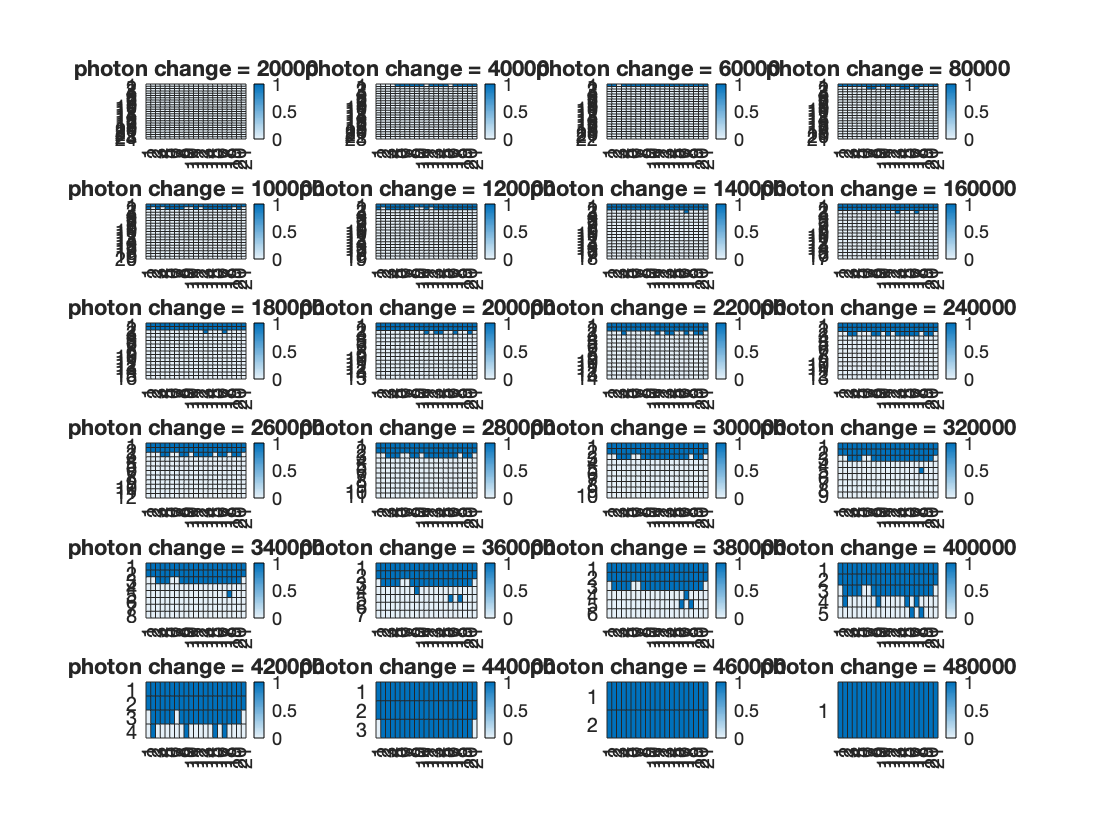

for j=1:24
    mean_all_diff2=zeros(25-j,21);
    for i=1:25-j
        mean_all_diff2(i,:)=mean_all(i+j,:)-mean_all(i,:);
    end
    diff=mean_all_diff2/3.96-std_all(1:25-j,:);
    diff_plot=diff;
    diff_plot(find(diff>=0))=1;
    diff_plot(find(diff<0))=0;
    subplot(6,4,j)
    h=heatmap(diff_plot);
    h.Title=['photon change = ',num2str(j*20000)];
    h.ColorLimits=[0 1];
end

This part is trying to answer a different question. Imagine for the the running vs resting experiment, what we want to illustrate is that lifetime is enough or much better at reflecting the running or resting state of the animal, across animals and time.

When we see 'across animals and time', what we are really trying to say is that regardless the expression level of the sensor, lifetime is better at predicting behavior state that intensity. To simulate this, what we need to do is pool samples with the same p1 (may corresponds to the same behavior state) but different sample size (corresponds to different expression level of the sensor) together, and decide the minimum photon count to still detect the lifetime difference between these with-same-p1 pools. Different from what I've done before, instead of deciding this threshold based on individual conditions (p1 and sample size), I'll pool different amount of conditions (same p1, different sample size) first, and then deciding the threshold.

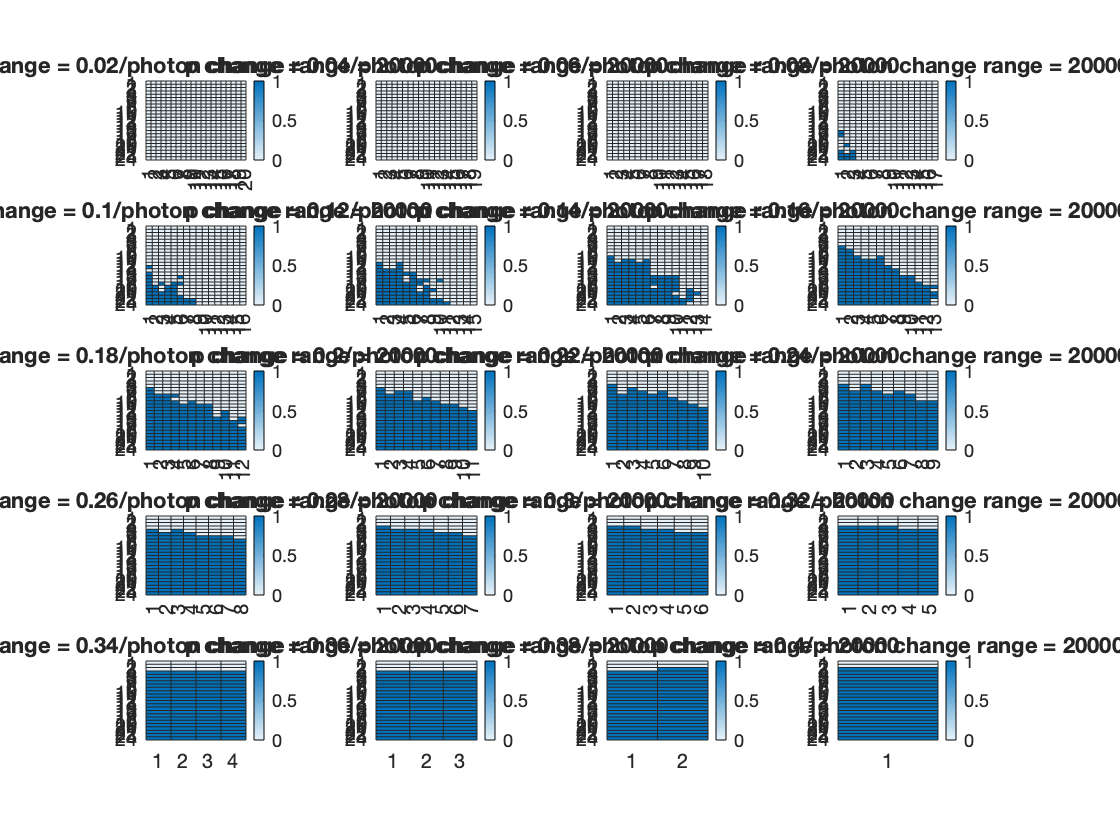



k=1;
mean_all_pool=zeros(25-k, 21);
std_all_pool=zeros(25-k, 21);
for i=1:25-k
    for j=1:21
        mean_all_pool(i,j)=mean([mean_all(i,j) mean_all(i+k,j)]);
        std_all_pool(i,j)=sqrt(std_all(i,j)^2+std_all(i+k,j)^2);
    end
end

for j=1:20
    mean_all_pool_diff=zeros(25-k,21-j);
    for i=1:21-j
        mean_all_pool_diff(:,i)=mean_all_pool(:,i+j)-mean_all_pool(:,i);
    end
    
    diff=mean_all_pool_diff/3.96-std_all_pool(:,1:(21-j));
    diff_plot=diff;
    diff_plot(find(diff>=0))=1;
    diff_plot(find(diff<0))=0;
    subplot(5,4,j)
    h=heatmap(diff_plot);
    h.Title=['p change = ',num2str(0.02*j),'/photon change range = ',num2str(20000*k)];
    h.ColorLimits=[0 1];
end

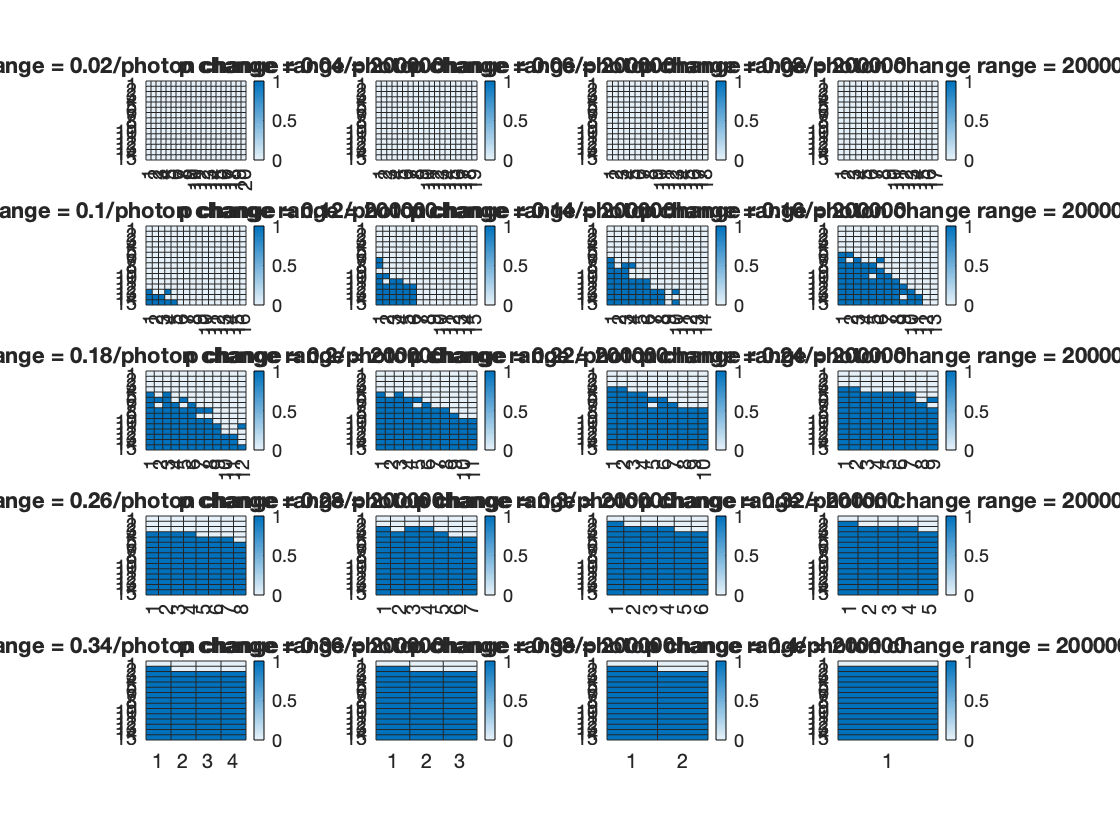

k=10;
mean_all_pool=zeros(25-k, 21);
std_all_pool=zeros(25-k, 21);
for i=1:25-k
    for j=1:21
        mean_all_pool(i,j)=mean([mean_all(i,j) mean_all(i+k,j)]);
        std_all_pool(i,j)=sqrt(std_all(i,j)^2+std_all(i+k,j)^2);
    end
end

for j=1:20
    mean_all_pool_diff=zeros(25-k,21-j);
    for i=1:21-j
        mean_all_pool_diff(:,i)=mean_all_pool(:,i+j)-mean_all_pool(:,i);
    end
    
    diff=mean_all_pool_diff/3.96-std_all_pool(:,1:(21-j));
    diff_plot=diff;
    diff_plot(find(diff>=0))=1;
    diff_plot(find(diff<0))=0;
    subplot(5,4,j)
    h=heatmap(diff_plot);
    h.Title=['p change = ',num2str(0.02*j),'/photon change range = ',num2str(20000*k)];
    h.ColorLimits=[0 1];
end


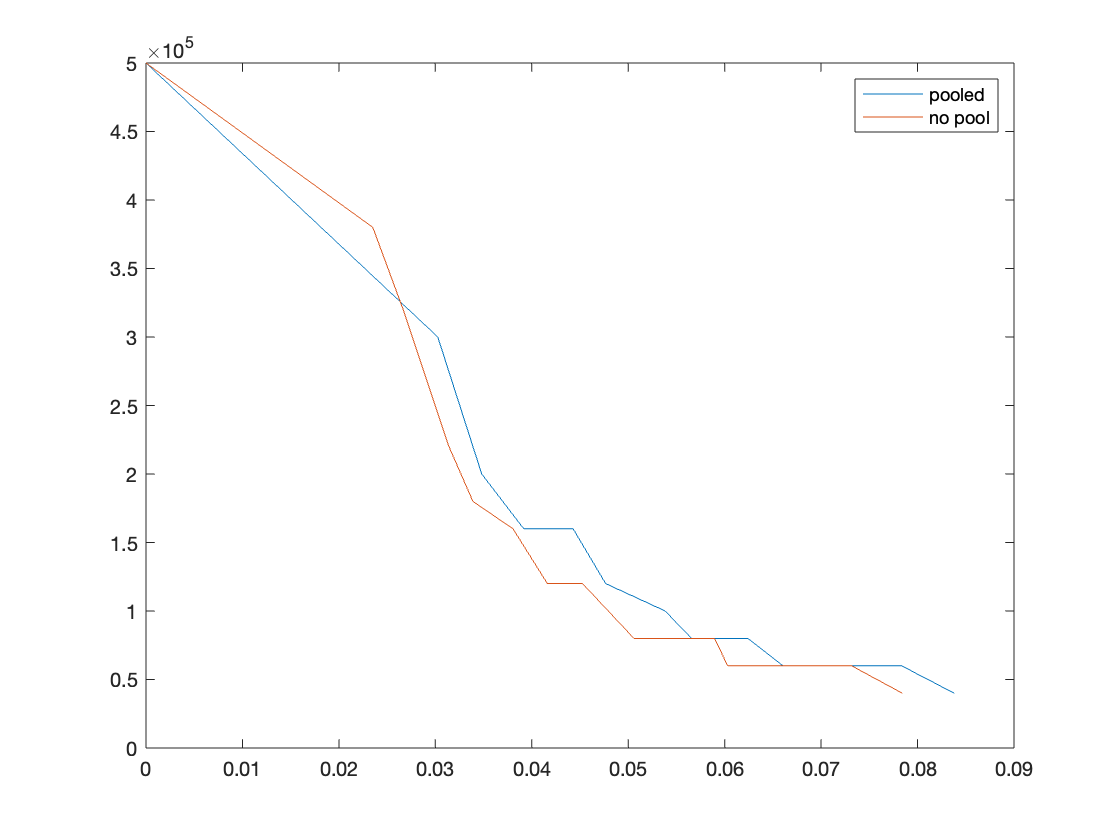



% k=10
detectable_line_10=[25 25 25 25 25 25 25 25 15 10 8 8 6 5 4 4 3 3 3 2];
detectable_lft_10=zeros(1,20);

for j=1:20
    mean_all_pool_diff=zeros(25-k,21-j);
    for i=1:21-j
        mean_all_pool_diff(:,i)=mean_all_pool(:,i+j)-mean_all_pool(:,i);
    end
    if detectable_line_10(j)==25
        detectable_lft_10(j)=0;
    else
        detectable_lft_10(j)=min(mean_all_pool_diff(detectable_line_10(j),:));
    end
end

figure
plot(detectable_lft_10,SS_samples(detectable_line_10))
hold on
plot(detectable_lft,SS_samples(detectable_line))
legend('pooled','no pool')
